# Lab 2: RTK GPS

The purpose of this lab was to collect data using the RTK GPS method (where both a gps puck and a base station (provided via MACors) work to provide a correction factor to GPS for more accurate results) and compare to regular GPS we took in Lab 1.

This matlab code is used to analyze the bag files taken in Lab 2

Uploading bag files

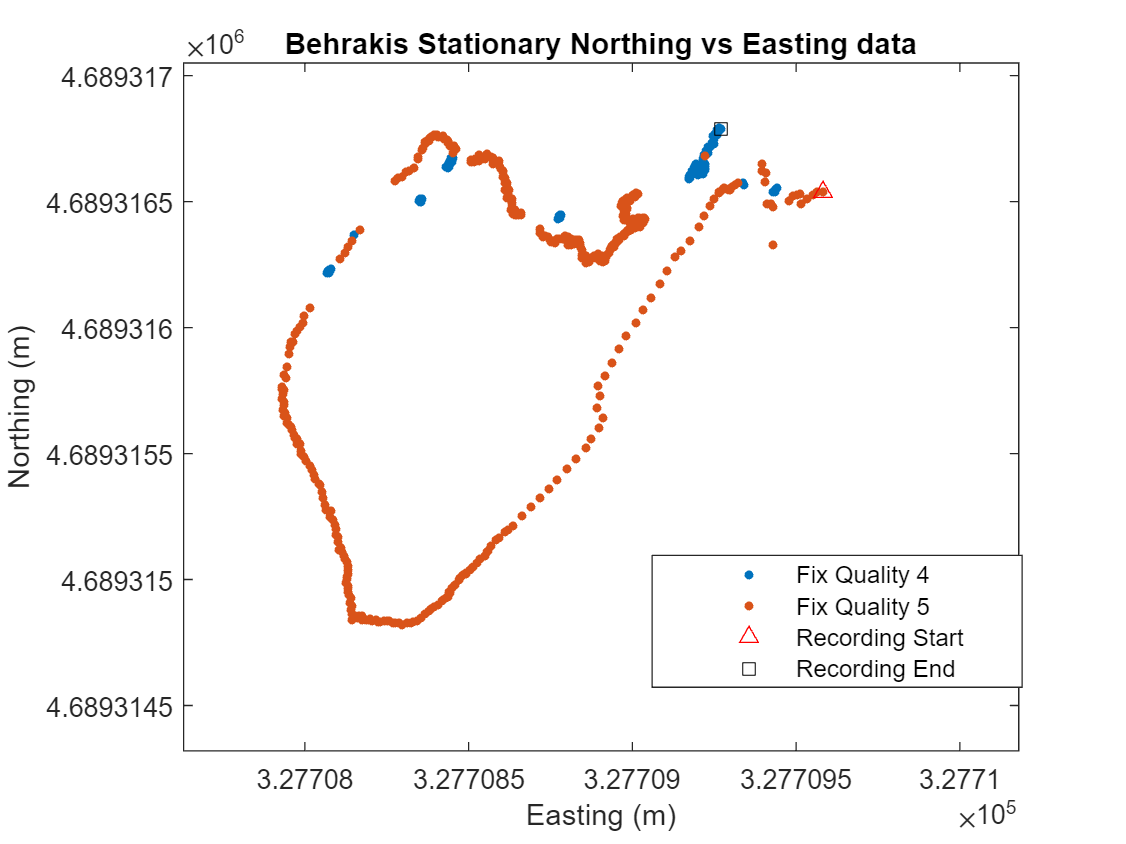

format short
bagStaticBehrakis = rosbag("stationary_berakhis.bag");
bagDynamicBehrakis = rosbag("walking_berakhis.bag");
bagStaticCentennial = rosbag("stationary_centennial.bag");
bagDynamicCentennial = rosbag("walking_centennial.bag");


bSel_SB = select(bagStaticBehrakis, 'Topic', '/gps');
msgStructs_SB = readMessages(bSel_SB,"DataFormat","struct");
Northing_SB = cellfun(@(m) double(m.UTMNorthing),msgStructs_SB);
Easting_SB = cellfun(@(m) double(m.UTMEasting),msgStructs_SB);
Fix_SB = cellfun(@(m) double(m.FixQuality),msgStructs_SB);

bSel_DB = select(bagDynamicBehrakis, 'Topic', '/gps');
msgStructs_DB = readMessages(bSel_DB,"DataFormat","struct");
Northing_DB = cellfun(@(m) double(m.UTMNorthing),msgStructs_DB);
Easting_DB = cellfun(@(m) double(m.UTMEasting),msgStructs_DB);
Fix_DB = cellfun(@(m) double(m.FixQuality),msgStructs_DB);

bSel_SC = select(bagStaticCentennial, 'Topic', '/gps');
msgStructs_SC = readMessages(bSel_SC,"DataFormat","struct");
Northing_SC = cellfun(@(m) double(m.UTMNorthing),msgStructs_SC);
Easting_SC = cellfun(@(m) double(m.UTMEasting),msgStructs_SC);
Fix_SC = cellfun(@(m) double(m.FixQuality),msgStructs_SC);


bSel_DC = select(bagDynamicCentennial, 'Topic', '/gps');
msgStructs_DC = readMessages(bSel_DC,"DataFormat","struct");
Northing_DC = cellfun(@(m) double(m.UTMNorthing),msgStructs_DC);
Easting_DC = cellfun(@(m) double(m.UTMEasting),msgStructs_DC);
Fix_DC = cellfun(@(m) double(m.FixQuality),msgStructs_DC);



figure
gscatter(Easting_SB, Northing_SB, Fix_SB)
title('Behrakis Stationary Northing vs Easting data')
xlabel('Easting (m)')
ylabel('Northing (m)')
hold on
plot(Easting_SB(1),Northing_SB(1),'^','MarkerEdgeColor','red')
plot(Easting_SB(length(Easting_SB)), Northing_SB(length(Northing_SB)),'s','MarkerEdgeColor','black')
hold off
legend('Fix Quality 4', 'Fix Quality 5', 'Recording Start', 'Recording End')

legend("Position", [0.57924,0.20423,0.32857,0.11905])

xlim([327707.63 327710.18])
ylim([4689314.32 4689317.05])




knownEasting_SB = Easting_SB(length(Easting_SB))

knownEasting_SB = 3.2771e+05

knownNorthing_SB = Northing_SB(length(Northing_SB))

knownNorthing_SB = 4.6893e+06

errors_SB = ((Easting_SB - knownEasting_SB).^2 + (Northing_SB - knownNorthing_SB).^2).^0.5

errors_SB =     0.3995
    0.3865
    0.3878
    0.3853
    0.3844
    0.3569
    0.3514
    0.3444
    0.3529
    0.4897


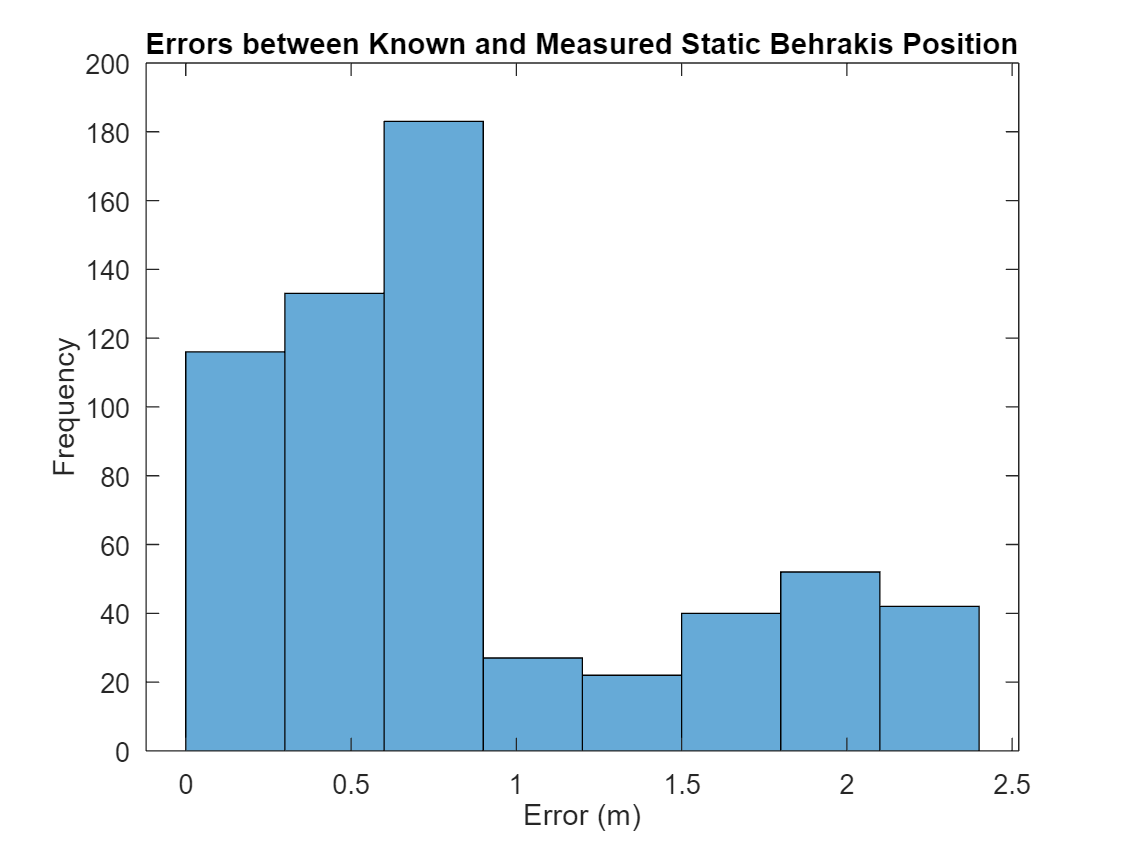

histogram(errors_SB)
title('Errors between Known and Measured Static Behrakis Position')
xlabel('Error (m)')
ylabel('Frequency')

RMSerror_SB = rms(errors_SB)

RMSerror_SB = 1.0740





gscatter(Easting_DB, Northing_DB, Fix_DB)
title('Behrakis Dynamic Northing vs Easting data')
xlabel('Easting (m)')
ylabel('Northing (m)')
legend('Fix Quality 1', 'Fix Quality 5')

pA = polyfit(Easting_DB(27:90), Northing_DB(27:90), 1);
fA = polyval(pA,Easting_DB(27:90));
PredictedNorthingA = fA;
ResidualSumSquaresA = sum((Northing_DB(27:90) - PredictedNorthingA).^2);
MeanSquaredErrorA = (1/length(Northing_DB(27:90)))*ResidualSumSquaresA

MeanSquaredErrorA = 337.0556


pB = polyfit(Easting_DB(91:164), Northing_DB(91:164), 1);
fB = polyval(pB,Easting_DB(91:164));
PredictedNorthingB = fB;
ResidualSumSquaresB = sum((Northing_DB(91:164) - PredictedNorthingB).^2);
MeanSquaredErrorB = (1/length(Northing_DB(91:164)))*ResidualSumSquaresB

MeanSquaredErrorB = 0.2649

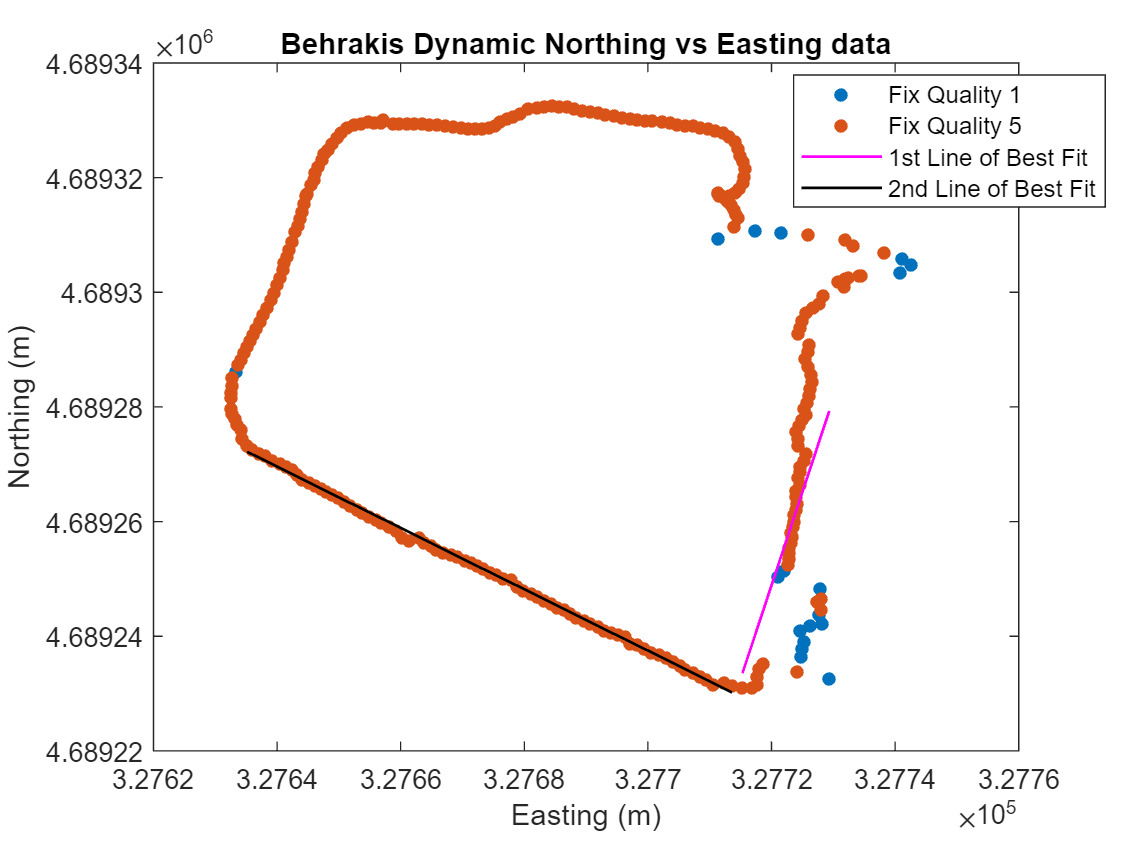

hold on
plot(Easting_DB(27:90),fA,'-','Color','magenta','LineWidth',1)
plot(Easting_DB(91:164),fB,'-','Color','black','LineWidth',1)
hold off
legend('Fix Quality 1', 'Fix Quality 5','1st Line of Best Fit','2nd Line of Best Fit')

xlim([327620 327760])
legend("Position", [0.70467,0.75489,0.27679,0.15595])


AvgMeanSquaredError = (MeanSquaredErrorB+MeanSquaredErrorA)/2

AvgMeanSquaredError = 168.6603

MeanSquaredErrorA

MeanSquaredErrorA = 337.0556

MeanSquaredErrorB

MeanSquaredErrorB = 0.2649


% gscatter(Easting_DB(29:90),Northing_DB(29:90),Fix_DB(29:90))
% 
% hold on 
% gscatter(Easting_DB(91:164),Northing_DB(91:164),Fix_DB(91:164))
% hold off
% title('THE(')
% legend
% 







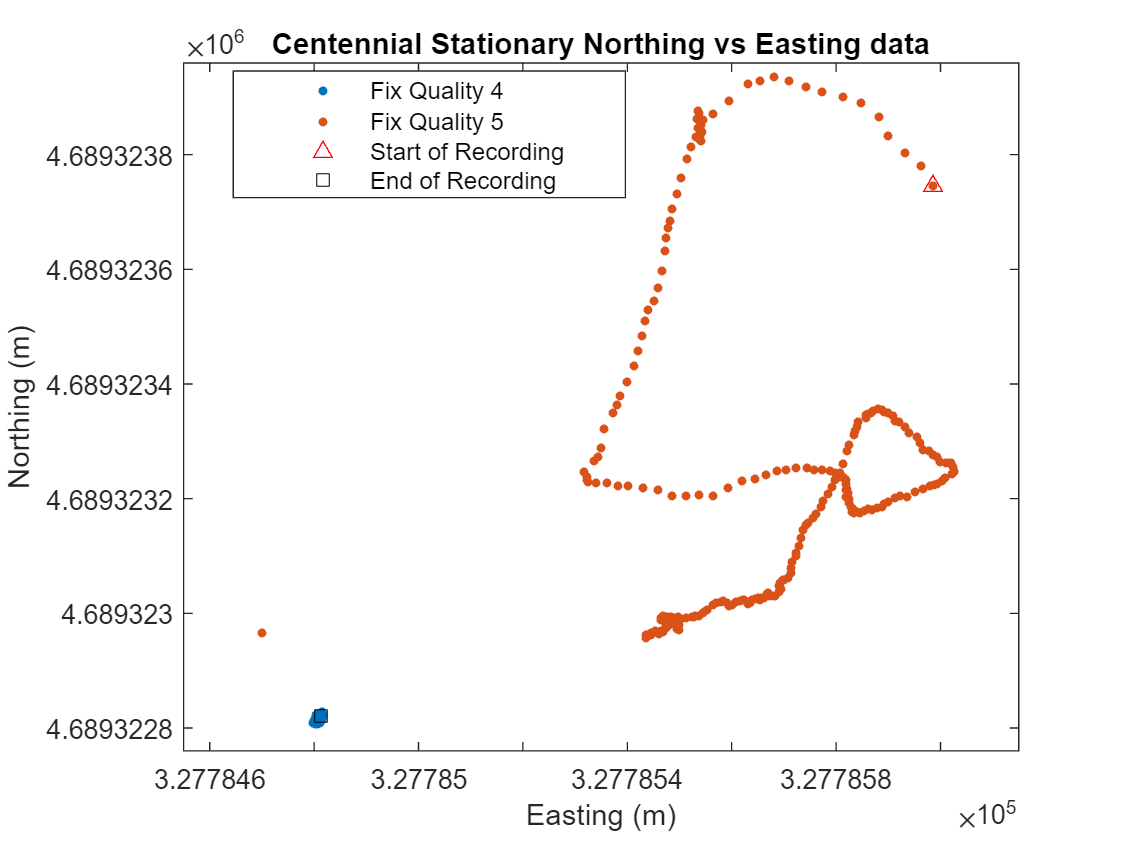


gscatter(Easting_SC, Northing_SC, Fix_SC)
title('Centennial Stationary Northing vs Easting data')
xlabel('Easting (m)')
ylabel('Northing (m)')
hold on
plot(Easting_SC(1),Northing_SC(1),'^','MarkerEdgeColor','red')
plot(Easting_SC(length(Easting_SC)), Northing_SC(length(Northing_SC)),'s','MarkerEdgeColor','black')
hold off
legend('Fix Quality 4', 'Fix Quality 5', 'Start of Recording', 'End of Recording')

legend("Position", [0.2074,0.78148,0.34821,0.11905])

xlim([327784.55 327786.15])
ylim([4689322.76 4689323.96])


knownEasting_SC = Easting_SC(length(Easting_SC))

knownEasting_SC = 3.2778e+05

knownNorthing_SC = Northing_SC(length(Northing_SC))

knownNorthing_SC = 4.6893e+06


errors_SC = ((Easting_SC - knownEasting_SC).^2 + (Northing_SC - knownNorthing_SC).^2).^0.5

errors_SC =     1.4932
    1.4970
    1.4890
    1.4849
    1.4953
    1.4886
    1.4714
    1.4516
    1.4381
    1.4244


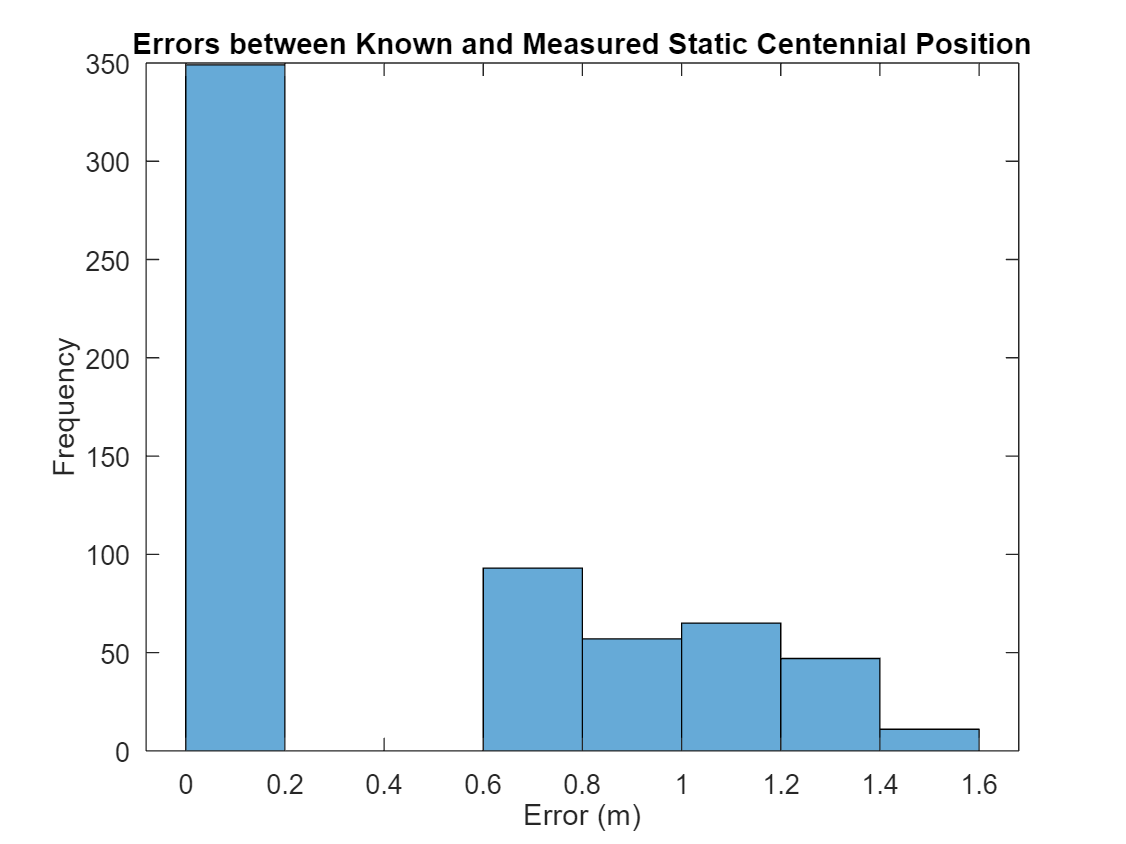

histogram(errors_SC)
title('Errors between Known and Measured Static Centennial Position')
xlabel('Error (m)')
ylabel('Frequency')

RMSerror_SC = rms(errors_SC)

RMSerror_SC = 0.6570

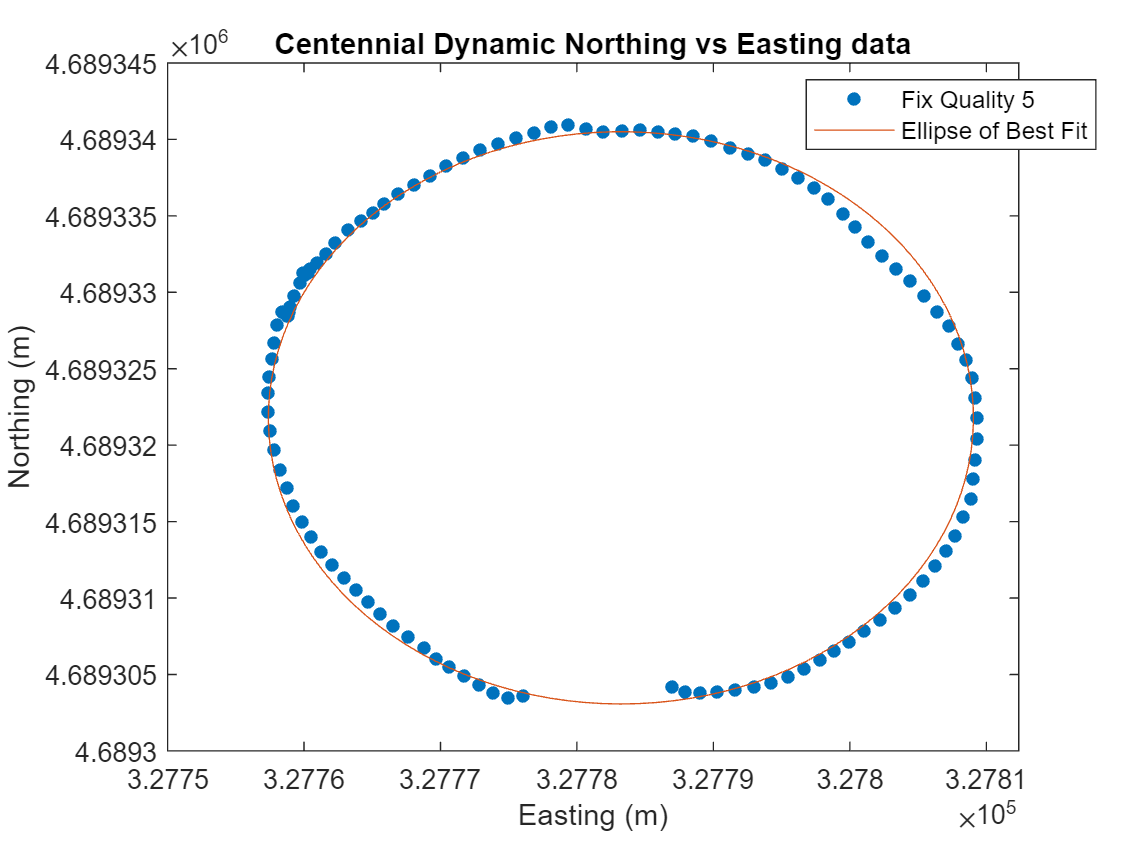





gscatter(Easting_DC(20:145), Northing_DC(20:145),Fix_DC(20:145))
title('Centennial Dynamic Northing vs Easting data')
xlabel('Easting (m)')
ylabel('Northing (m)')
ellipse_vals = fit_ellipse(Easting_DC(20:145),Northing_DC(20:145));
t = linspace(-.5*pi,1.5*pi, length(Easting_DC(20:145)));
a = ellipse_vals.a;
b = ellipse_vals.b;
X0 = ellipse_vals.X0_in;
Y0 = ellipse_vals.Y0_in;
x = X0 + a*cos(t);
x = x';
y = Y0 + b*sin(t);
y = y';
hold on
plot(x,y);
legend("Fix Quality 5","Ellipse of Best Fit")
hold off

legend("Position", [0.7163,0.8234,0.25714,0.082143])


error = zeros(length(Easting_DC(20:145)),1);
error_index=zeros(length(Easting_DC(20:145)),1);
error_val = zeros(length(Easting_DC(20:145)),1);
for i = 1:length(Easting_DC(20:145));
    xcoord = Easting_DC(19+i);
    ycoord = Northing_DC(19+i);
    for b = 1:length(Easting_DC(20:145));
        error(b)= sqrt((xcoord - x(b))^2+(ycoord - y(b))^2);
    end
    error_index(i) = find(error==min(error));
    error_val(i) = min(error);
end
 
error_val;
mean_error = rms(error_val)

mean_error = 0.6441

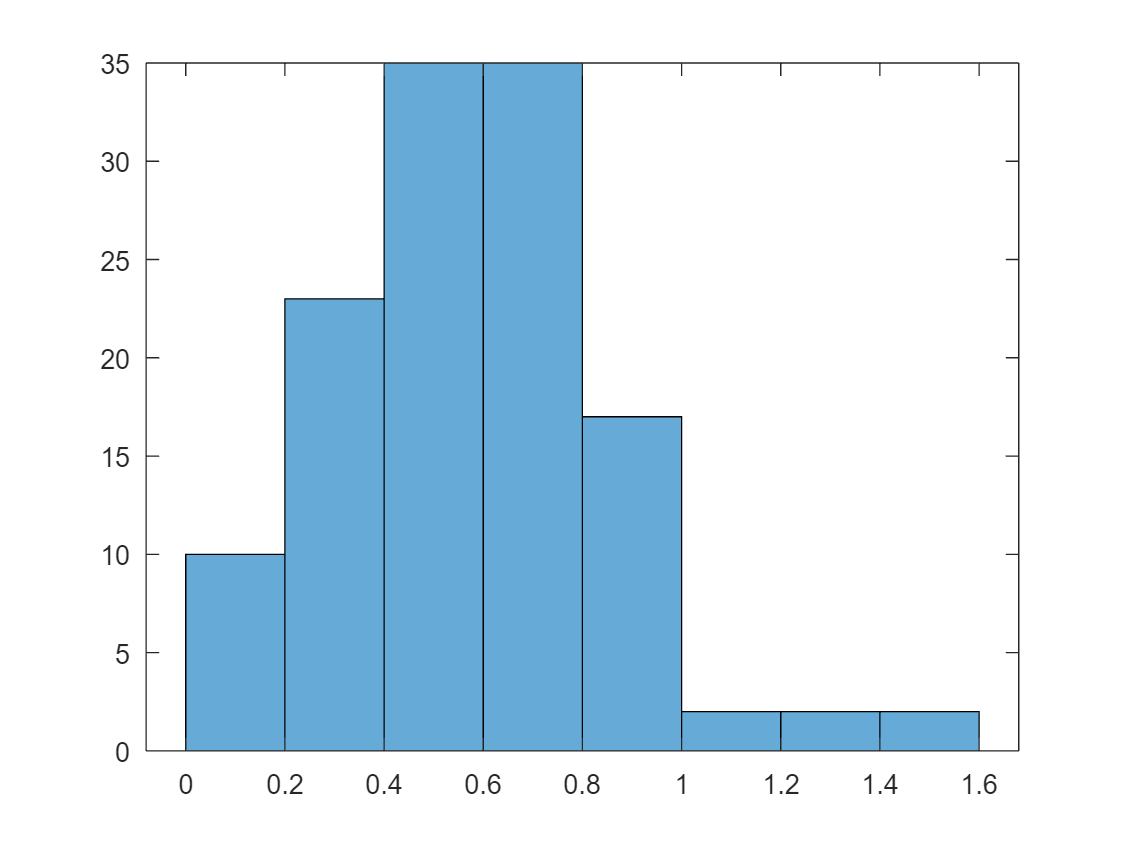

histogram(error_val)

rms(error_val)

ans = 0.6441